Limpar 

close all
clear
clc

# Lab 04 

Figura 01- Amplificador MOSFET-E com polarização por divisor de tensão (modelo de circuito para os calculos).  

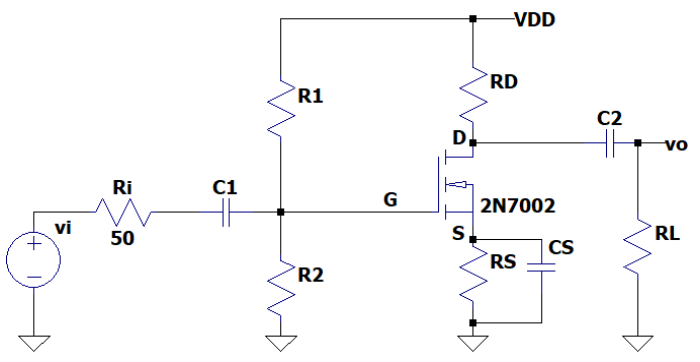

Fonte: PDF JFET e MOSFET do material de aula.

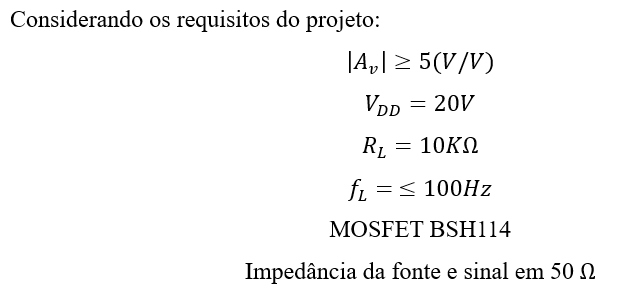

## Analise CC do circuito:

VDD=20;%(V) Regra estabelecida
Ri = 50;%Regra estabelecida

Projeto utilizando MOSFET BSH114

VGSth=1.2; %datasheet
IDon =5;%datasheet
VGSon =4.5;%datasheet

Considerando:

R1=600e+3; %Escolha do projetista
R2=R1;
Vg=VDD/2

Vg = 10

Zi = R1/2 %Impedância de entrada

Zi = 300000

Calculo do K


$$k=\frac{I_{D{\left(on\right)}} }{{{\left(V_{GS{\left(on\right)}} -V_{GS{\left(th\right)}} \right)}}^2 }$$


k = IDon/(VGSon-VGSth)^2

k = 0.4591

RS = 200 %Escolha do projetista

RS = 200

Obtendo a Corrente IDQ e a tensão VGSQ:

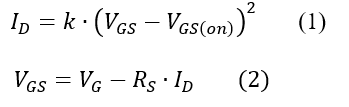

Resolvendo as raizes obtidas da substituição de (2) em (1) temos:

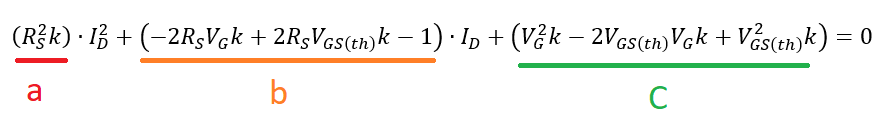

a =k*(RS^2)

a = 1.8365e+04

b=((-2*RS*Vg*k)+(2*RS*VGSth*k)-1)

b = -1.6172e+03

c=(((Vg^2)*k)-(2*VGSth*Vg*k)+((VGSth^2)*k))

c = 35.5556

Resolvendo equação de Bhaskara temos nosso ID1 e ID2 

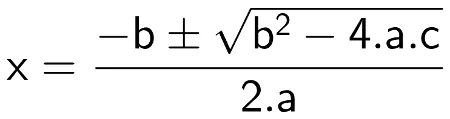

ID1 = (-b+(sqrt((b^2)-4*a*c)))/(2*a)

ID1 = 0.0456

ID2 = (-b-(sqrt((b^2)-4*a*c)))/(2*a)

ID2 = 0.0425

Aplicando na equação (2) obtemos o VGS das correntes e comparamos qual deles atende a nossa especificação:

VGS1 = Vg-RS*ID1

VGS1 = 0.8849

VGS2 = Vg-RS*ID2

VGS2 = 1.5042




if (VGS1<VGSth && VGS2>VGSth)  
    fprintf 'VGS1 Não atende'
    VGSQ = VGS2
    IDQ = ID2
end    

VGS1 Não atende

VGSQ = 1.5042

IDQ = 0.0425

if (VGS2<VGSth && VGS1>VGSth)
    fprintf 'VGS2 não atende'
        VGSQ = VGS1
        IDQ = ID1
end
if (VGS2<VGSth && VGS1<VGSth)
    fprintf 'nenhum atende recalcular'
end
if (VGS2>VGSth && VGS1>VGSth)
    fprintf 'Ambos atendem escolha qual VGS usar, padrão é VGS1'
    VGSQ = VGS1%Alterar para VGS2 caso queira e ambos possam ser utilizados
    IDQ = ID1 %Alterar para ID2 caso escolher VGS2
end

*o progrma ira partir automaticamente apos obter o valor, e usara VGSQ e IDQque atendam as condições para efetuar os calculos apartir de aqui!

## Analise CA do circuito:

Figura 2- Modelo CA do circuito  

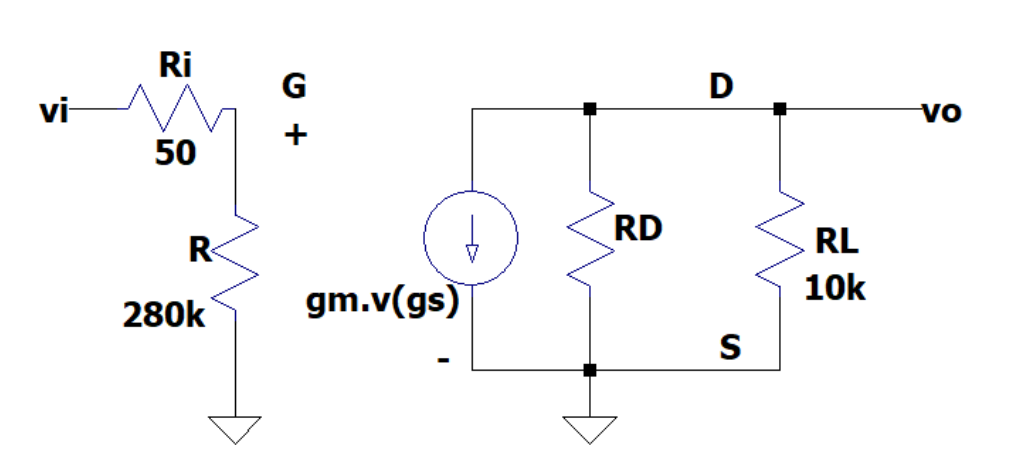

Fonte: PDF JFET e MOSFET do material de aula.

Para obdecer os requisitos do projeto escolha o ganho:

*Obs.: esta sendo desconsiderado rd como ja visto no material e as seguintes equações:

AV = 50 %(V/V)  Escolha do projetista

AV = 50

RL = 10e+3; %requisitos
gm = (2*IDQ)/(VGSQ-VGSth)

gm = 0.2793

 
RD = 1/((gm/AV)-(1/RL))

RD = 182.2745

RS

RS = 200

*Por questões praticas caso RD seja seja muito proximo ou ligeiramente abaixo de RS deve ser escolhido um valor um pouco acima de RS, e nesse caso é necessario a analise do usuario no codigo comentando a equação e atribuindo um valor correto a RD.

Analise da resposta em frequência do filtro:

fmin = 70 %obedecer a frequencia minima fl<100 Escolha do projetista  

fmin = 70

WCs = 2*pi*fmin

WCs = 439.8230

WC1 = WCs/10

WC1 = 43.9823

CALCULO DOS CAPACITORES:

Figura 3- Modelo T do circuito em análise com a inclusão dos capacitores para a avaliação.

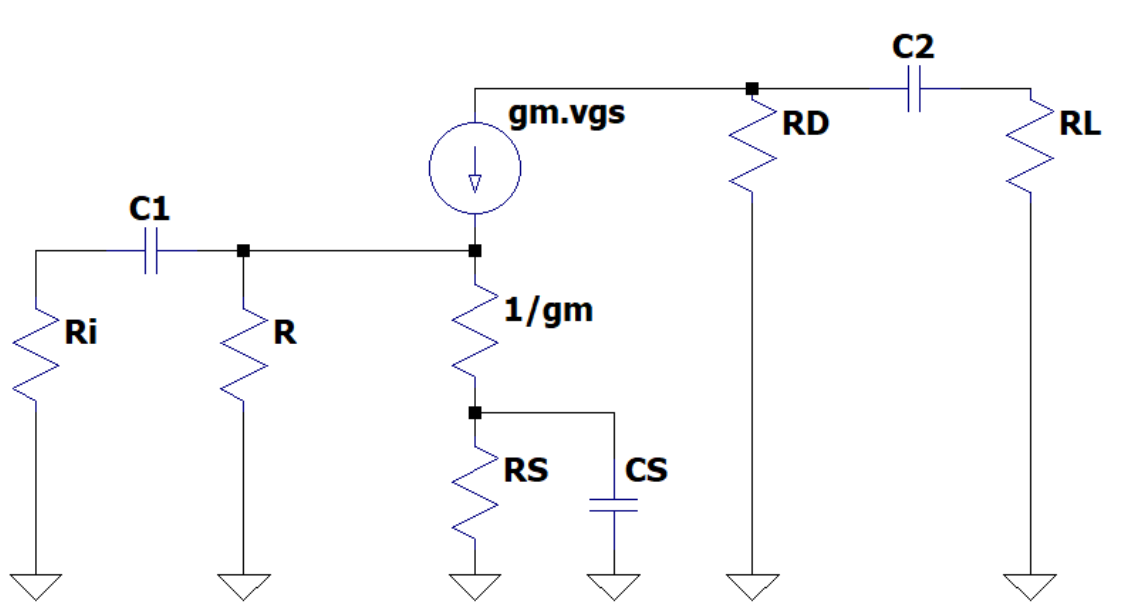

Fonte: PDF JFET e MOSFET do material de aula.

PARA O CAPACITOR C1:

Figura 4- Circuito para analise de C1.

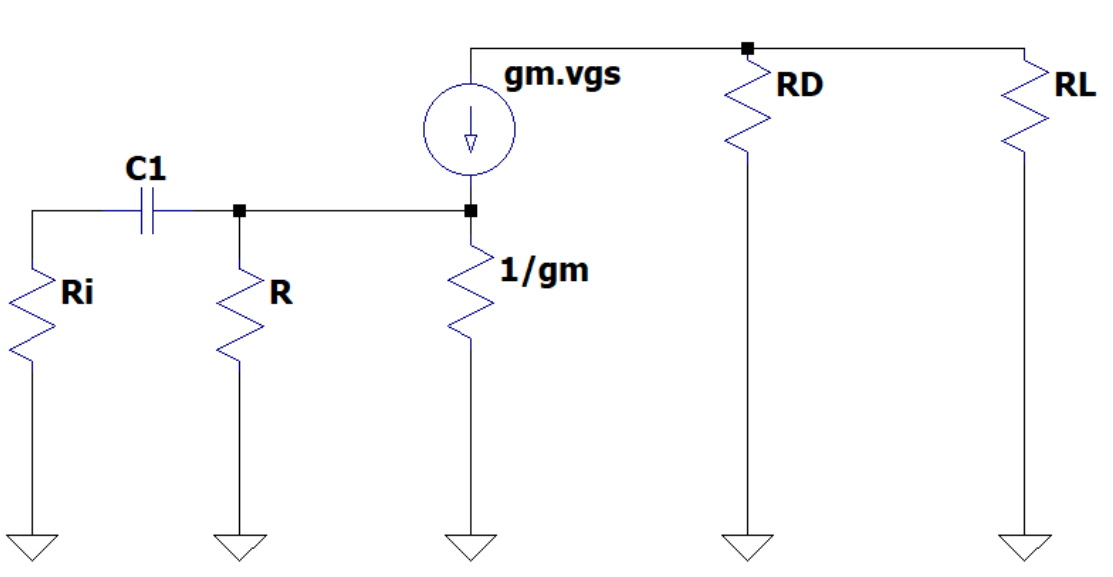

Fonte: PDF JFET e MOSFET do material de aula.

R = R1/2;
RC1 = Ri+R

RC1 = 300050

C1 = 1/(WC1*RC1)

C1 = 7.5775e-08

PARA O CAPACITOR C2:

Figura 5 - Circuito para analise de C2.

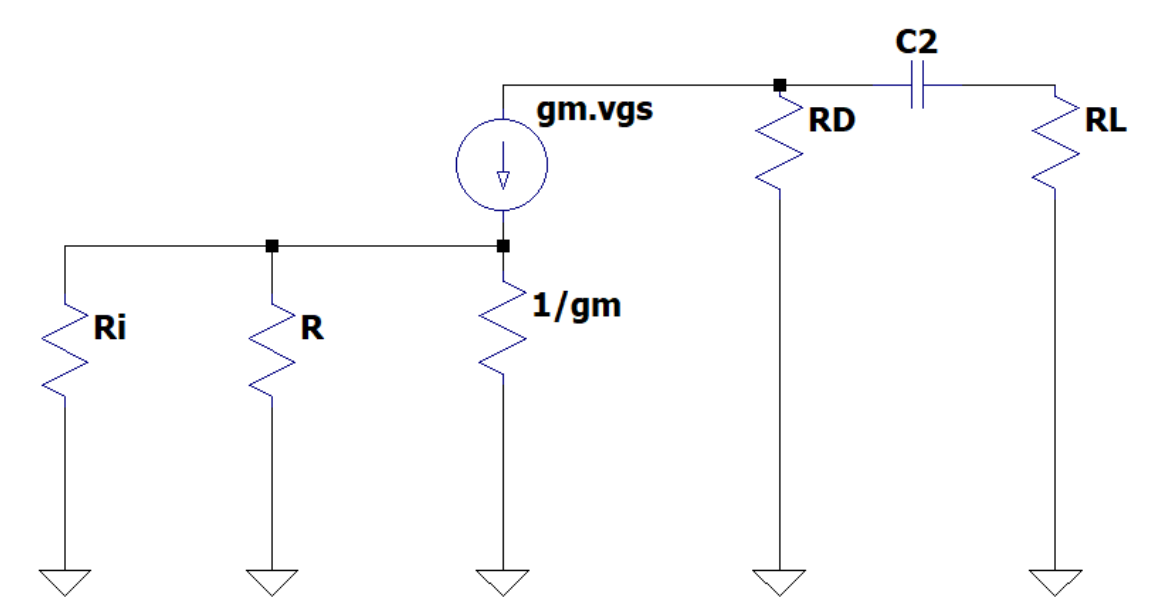

Fonte: PDF JFET e MOSFET do material de aula.

RC2 = RD+RL

RC2 = 1.0182e+04

C2 = 1/(WC1*RC2)

C2 = 2.2329e-06

PARA O CALCULO DO CS

Figura 5 - Circuito para analise de CS

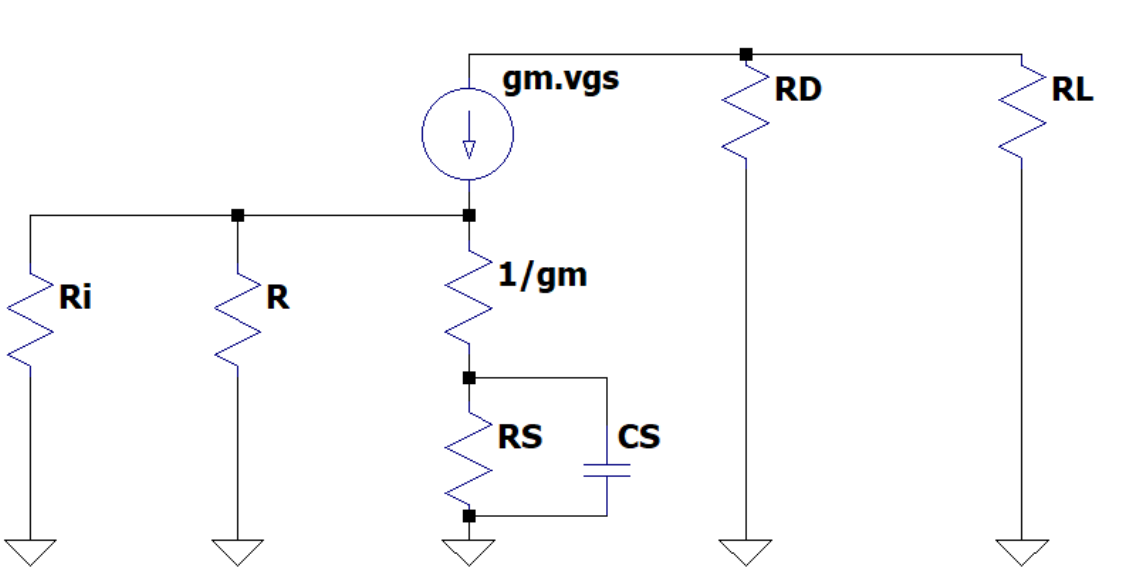

Fonte: PDF JFET e MOSFET do material de aula.

RCS = ((1/RS)+(1/(1/gm)))^-1

RCS = 3.5173

CS = 1/(WCs*RCS)

CS = 6.4642e-04